# CDL Channel Model Customization with Ray Tracing

This example shows how to customize the CDL channel model parameters by using the output of a ray tracing analysis. The example shows how to: 

- Specify the location of a transmitter and a receiver in a 3D environment.

- Use ray tracing to calculate the geometric aspects of the channel: number of rays, angles, delays and attenuations.

- Configure the CDL channel model with the result of ray tracing analysis.

- Specify the channel antenna arrays using Phased Array System Toolbox™.

- Visualize the transmit and receive array radiation patterns based on singular value decomposition of a perfect channel estimate.

## Base Station and UE Configuration

The example assumes that both the base station and the UE use rectangular arrays. The array orientations are specified as a pair of values representing azimuth and elevation. Both angles are in degrees.

fc = 6e9;                             % carrier frequency (Hz)
bsPosition = [45.494449,-73.561667];  % lat, lon
bsAntSize = [1 1]; % [8 8];                    % number of rows and columns in rectangular array (base station)
bsArrayOrientation = [-30 0].';       % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards) in deg

% UEs 1-3: like the DeepMIMO data (on the street)
ue1Position = [45.494415,-73.560592]; % lat, lon
ueAntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ueArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg

ue2Position = [45.494500,-73.560375]; % lat, lon
ue2AntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ue2ArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg

ue3Position = [45.495106,-73.561076]; % lat, lon
ue3AntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ue3ArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg


% UE 4 closer to the BS than the training data (in Auto parking)
ue4Position = [45.494301,-73.561334]; % lat, lon
ue4AntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ue4ArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg

% UE 5: further to the BS than the training data (in the yard)
ue5Position = [45.493975,-73.559822]; % lat, lon
ue5AntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ue5ArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg

% UE 6: totally different (no LOS)
ue6Position = [45.494599,-73.560993]; %[45.493801,-73.560900]; % lat, lon
ue6AntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ue6ArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg
% also no LOS: [45.494563,-73.561015]; (on the Rue Peel)

reflectionsOrder = 1;                 % number of reflections for ray tracing analysis (0 for LOS)
 
% Bandwidth configuration, required to set the channel sampling rate and for perfect channel estimation
SCS = 30; % 15; % subcarrier spacing
NRB = 51; % number of resource blocks, SCS*NRB*12 MHz bandwidth for transmission

## Import and Visualize 3-D Environment with Buildings for Ray Tracing

Launch Site Viewer with buildings in ETS. For more information about the osm file, see [1].

if exist('viewer','var') && isvalid(viewer) % viewer handle exists and viewer window is open
    clearMap(viewer);
else
    viewer = siteviewer("Basemap","openstreetmap","Buildings","map.osm");    
end

## Create Base Station and UE

Locate the base station and the UE on the map.

bsSite = txsite("Name","Base station", ...
    "Latitude",bsPosition(1),"Longitude",bsPosition(2),...
    "AntennaAngle",bsArrayOrientation(1:2),...
    "AntennaHeight",4,...  % in m
    "TransmitterFrequency",fc);

ue1Site = rxsite("Name","UE1", ...
    "Latitude",ue1Position(1),"Longitude",ue1Position(2),...
    "AntennaHeight",1,... % in m
    "AntennaAngle",ueArrayOrientation(1:2));

ue2Site = rxsite("Name","UE2", ...
    "Latitude",ue2Position(1),"Longitude",ue2Position(2),...
    "AntennaHeight",1,... % in m
    "AntennaAngle",ue2ArrayOrientation(1:2));

ue3Site = rxsite("Name","UE3", ...
    "Latitude",ue3Position(1),"Longitude",ue3Position(2),...
    "AntennaHeight",1,... % in m
    "AntennaAngle",ue3ArrayOrientation(1:2));

ue4Site = rxsite("Name","UE4", ...
    "Latitude",ue4Position(1),"Longitude",ue4Position(2),...
    "AntennaHeight",1,... % in m
    "AntennaAngle",ue4ArrayOrientation(1:2));

ue5Site = rxsite("Name","UE5", ...
    "Latitude",ue5Position(1),"Longitude",ue5Position(2),...
    "AntennaHeight",1,... % in m
    "AntennaAngle",ue5ArrayOrientation(1:2));

ue6Site = rxsite("Name","UE6", ...
    "Latitude",ue6Position(1),"Longitude",ue6Position(2),...
    "AntennaHeight",1,... % in m
    "AntennaAngle",ue6ArrayOrientation(1:2));

Visualize the location of the base station and the UE. The base station is on top of a building.

show(bsSite);
show(ue1Site);
show(ue2Site);
show(ue3Site);
show(ue4Site);
show(ue5Site);
show(ue6Site);

## Ray Tracing Analysis

Perform ray tracing analysis using the shooting and bouncing rays (SBR) method. The SBR method includes effects from surface reflections and diffractions but does not include effects from refraction or scattering.

pm = propagationModel("raytracing","Method","sbr","MaxNumReflections",reflectionsOrder);
rays1 = raytrace(bsSite,ue1Site,pm,"Type","pathloss");
rays2 = raytrace(bsSite,ue2Site,pm,"Type","pathloss");
rays3 = raytrace(bsSite,ue3Site,pm,"Type","pathloss");
rays4 = raytrace(bsSite,ue4Site,pm,"Type","pathloss");
rays5 = raytrace(bsSite,ue5Site,pm,"Type","pathloss");
rays6 = raytrace(bsSite,ue6Site,pm,"Type","pathloss");

Display the rays in Site Viewer.

plot(rays1{1})
plot(rays2{1})
plot(rays3{1})
plot(rays4{1})
plot(rays5{1})
plot(rays6{1})

From the obtained rays, get the times of arrival, the average path gains, and the angles of departure and arrival. For simplicity, normalize the propagation delay so that the first path occurs at time 0 sec, corresponding to no delay. Use the path loss to obtain the average path gains. 

UEs coordinate limits on Rue Peel

Peel1 = [45.494840,-73.561236];
Peel2 = [45.494844,-73.561273];
Peel3 = [45.494164,-73.559462];
Peel4 = [45.494108,-73.559495];

UEs coordinate limits on Rue William

Will1 = [45.495328,-73.560852];
Will2 = [45.495371,-73.560918];
Will3 = [45.494852,-73.561230];
Will4 = [45.494883,-73.561308];
% Loop to gen rays first, to see if there is any error before generating
% pilots, channels,...

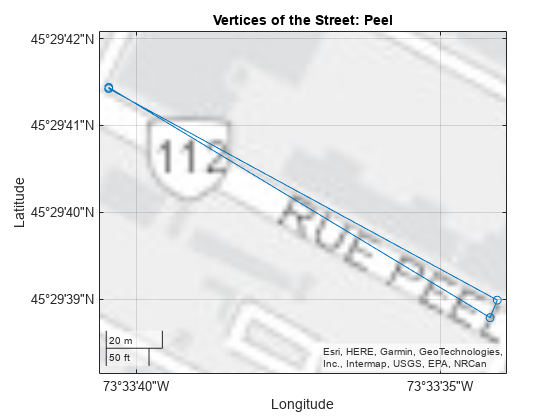

UE_grid = cell(1,2);
UE_grid{1}.street = 'Peel'; 
    UE_grid{1}.vertice{1} = [45.494844,-73.561273];
    UE_grid{1}.vertice{2} = [45.494840,-73.561236];
    UE_grid{1}.vertice{3} = [45.494164,-73.559462];
    UE_grid{1}.vertice{4} = [45.494108,-73.559495];
UE_grid{2}.street = 'William'; 
    UE_grid{2}.vertice{1} = [45.495371,-73.560918];
    UE_grid{2}.vertice{2} = [45.495328,-73.560852];
    UE_grid{2}.vertice{3} = [45.494852,-73.561230];
    UE_grid{2}.vertice{4} = [45.494883,-73.561308];

% Extract coordinates from UE_grid
latitudes = [UE_grid{1}.vertice{1}(1), UE_grid{1}.vertice{2}(1), ...
             UE_grid{1}.vertice{3}(1), UE_grid{1}.vertice{4}(1), ...
             UE_grid{1}.vertice{1}(1)]; % Closing the loop
longitudes = [UE_grid{1}.vertice{2}(2), UE_grid{1}.vertice{2}(2), ...
              UE_grid{1}.vertice{3}(2), UE_grid{1}.vertice{4}(2), ...
              UE_grid{1}.vertice{2}(2)]; % Closing the loop

% Create a geographic plot
figure;
geoplot(latitudes, longitudes, '-o');
title('Vertices of the Street: Peel');
grid on;

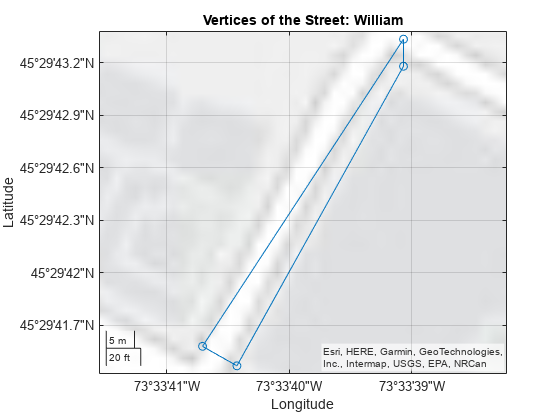



% Extract coordinates from UE_grid
latitudes = [UE_grid{2}.vertice{1}(1), UE_grid{2}.vertice{2}(1), ...
             UE_grid{2}.vertice{3}(1), UE_grid{2}.vertice{4}(1), ...
             UE_grid{2}.vertice{1}(1)]; % Closing the loop
longitudes = [UE_grid{2}.vertice{2}(2), UE_grid{2}.vertice{2}(2), ...
              UE_grid{2}.vertice{3}(2), UE_grid{2}.vertice{4}(2), ...
              UE_grid{2}.vertice{2}(2)]; % Closing the loop

% Create a geographic plot
figure;
geoplot(latitudes, longitudes, '-o');
title('Vertices of the Street: William');
grid on;

Generate points inside a rectangle by dividing its length by 100 and its width by 50 to get 5000 points

% % Coordinates of the four vertices (assuming they are in order: A, B, C, D)
% A = [x1, y1];
% B = [x2, y2];
% C = [x3, y3];
% D = [x4, y4];
% 
% % Number of divisions
% num_div_x = 100;  % along one pair of opposite sides
% num_div_y = 50;   % along the other pair of opposite sides
% 
% % Generate points inside the quadrilateral
% points = zeros(num_div_x * num_div_y, 2);  % Preallocate for efficiency
% index = 1;
% 
% for i = 0:num_div_x
%     for j = 0:num_div_y
%         % Interpolation along the x-direction
%         P1_x = (1 - i/num_div_x) * A(1) + (i/num_div_x) * B(1);
%         P1_y = (1 - i/num_div_x) * A(2) + (i/num_div_x) * B(2);
% 
%         P2_x = (1 - i/num_div_x) * D(1) + (i/num_div_x) * C(1);
%         P2_y = (1 - i/num_div_x) * D(2) + (i/num_div_x) * C(2);
% 
%         % Interpolation along the y-direction
%         point_x = (1 - j/num_div_y) * P1_x + (j/num_div_y) * P2_x;
%         point_y = (1 - j/num_div_y) * P1_y + (j/num_div_y) * P2_y;
% 
%         points(index, :) = [point_x, point_y];
%         index = index + 1;
%     end
% end
% 
% % Display the points (optional)
% scatter(points(:,1), points(:,2), '.');
% axis equal;


*Copyright 2020-2023 The MathWorks, Inc.*